# Desarrollo Laboratorio 1 - Robótica 2021-II

### Edgar Alejandro Ruíz Velasco

### Jesus Daniel Caballero Colina

### Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

## Características y modelo del robot  

**1. Busque información técnica del robot, obtenga catálogos de fabricante, presente en el informe:**

- **Imagen del robot.**

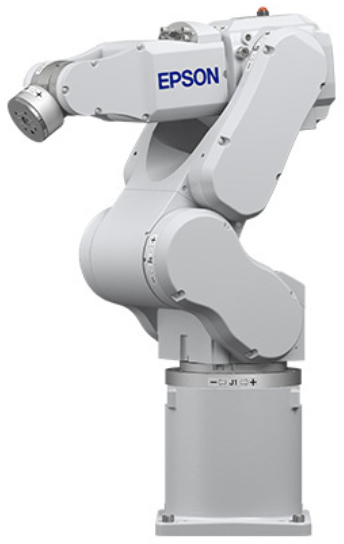        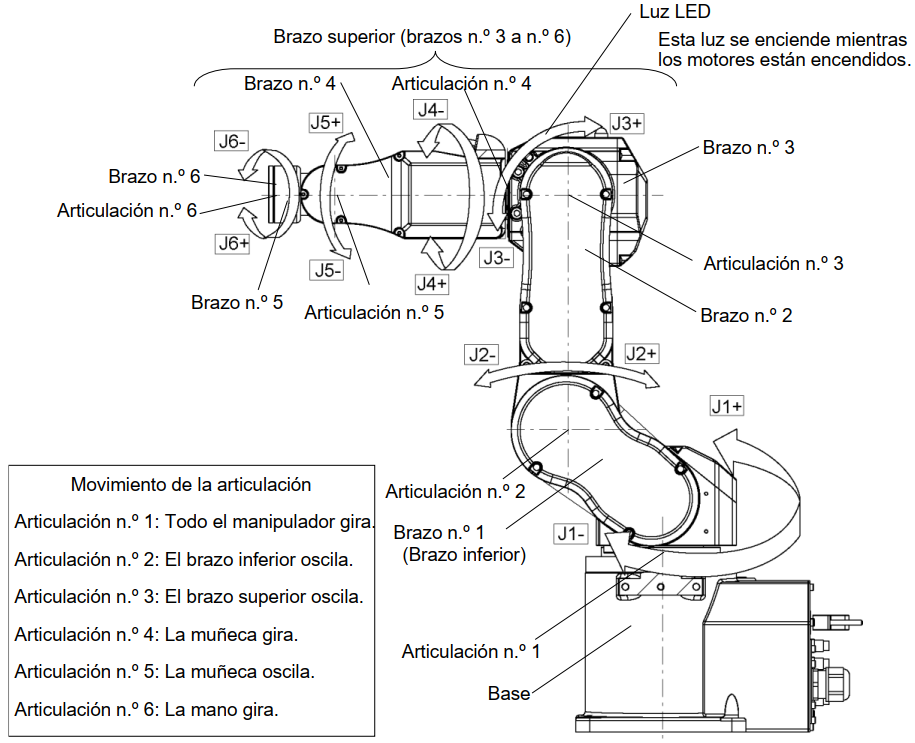

- **Capacidad de carga.**

La carga nominal de este robot es de 1kg y la carga maxima que puede operar es de 4kg, sin embargo se pueden alcanzar los 5kg si se realizan restricciones en la pose del robot, ésto se consigue restringiendo la postura del brazo Nº5 hacia abajo disminuyendo el angulo que éste forma con el plano del suelo en función de la carga.

- **Alcance vertical y horizontal.**

Para el máximo alcance horizontal este modelo C4 (Con numero serial C4-A601) tiene un alcance de 600mm en el punto P (que corresponde  a la intersección de los ejes de las articulaciones 4 y 6) y alcance máximo de 665mm (en el punto del efecto final).

Para el máximo alcance vertical se tiene un alcance de 500mm en el punto P y alcance máximo de 565mm.

Nota: Estas medidas son tomadas apartir de un origen situado en el centro de la base como se muestra en la siguiente figura:

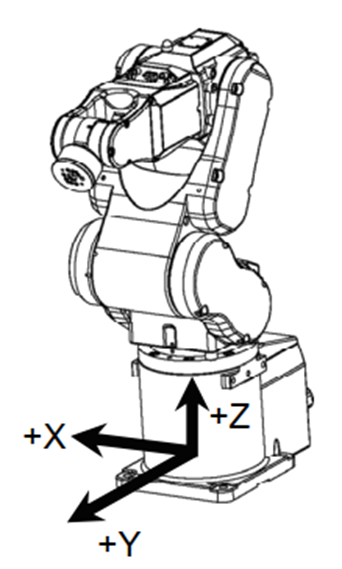

- **Repetibilidad.**

Se indica un error de repetibilidad de 0.02 mm mediado con tiempos del ciclos promedios a 300 mm de recorrido de 0,39 s (Velocidad 100 / Aceleración 100) y 0,37 s (Velocidad 100 / Aceleración 120).

- **Gráfica(s) de espacio alcanzable.**

Se debe tener en cuenta que para una mejor visualización del espacio alcanzable se debe analizar dejando algunas articulaciones constantes:

- **VISTA LATERAL**: Variando las articulaciones 2, 3 y 5 se construye el siguiente espacio de trabajo:

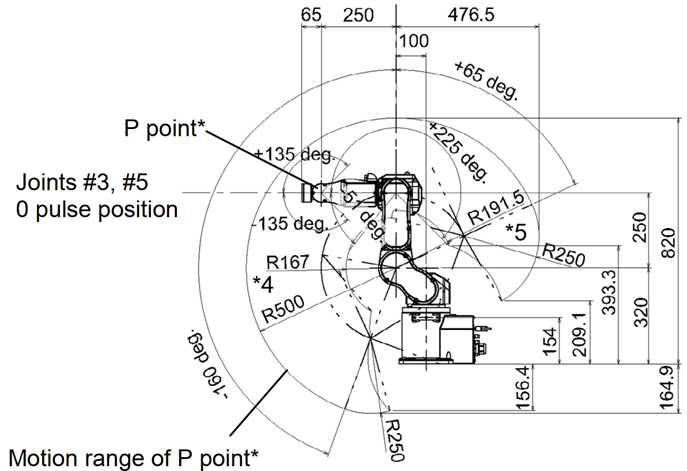

- *4 : El punto P desde la parte superior con la articulación n.º 3 que desciende -51° (Centro de la articulación n.º 2 – Centro del punto P)

- *5 : El punto P desde la parte superior con la articulación n.º 3 que se inclina +225! (Centro de la articulación n.º 2 – Centro del punto P)  

Cabe destacar que para la delimitación de este espacio de trabajo se tuvo que tener en cuenta el peor caso de limitaciones, indicado al analizar las gráficas de restricción de operación:

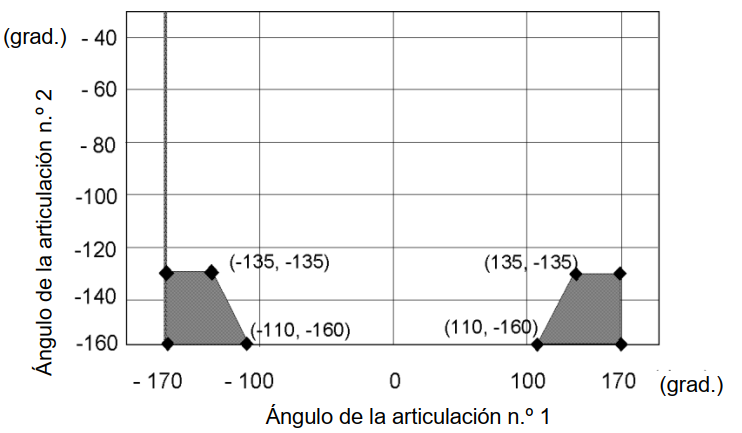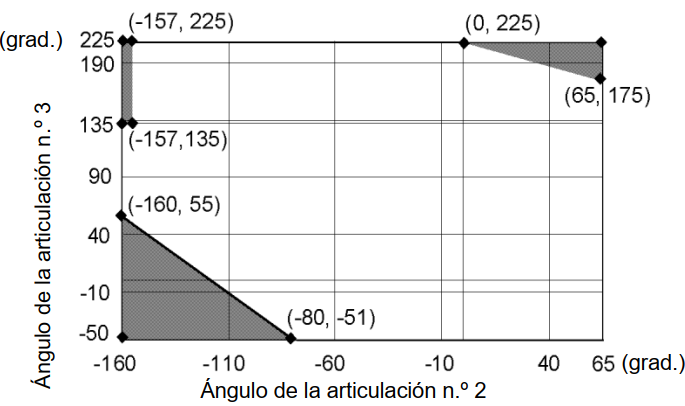

Lo cual indica que para $J_1 =\left\lbrack -170,-135\right\rbrack \bigcup \left\lbrack 135,170\right\rbrack$ el rango de movimiento de la articulación $J_2 =\left\lbrack -160,65\right\rbrack$ a $J_2 =\left\lbrack -135,65\right\rbrack$.

            2. **VISTA SUPERIOR:** Variando las articulación 1 se construye el siguiente espacio de trabajo:

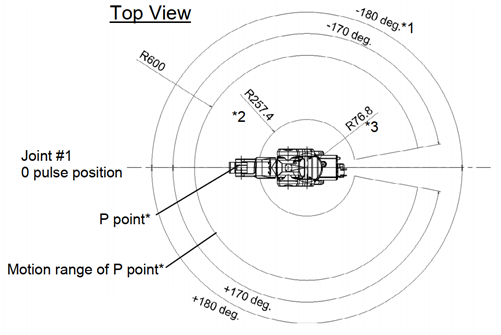

- *1 : La articulación n.º 1 sin tope mecánico ($\pm$180°), Para conocer el procedimiento de retiro del tope mecánico, consulte 

- *2 : El punto P desde la parte superior con la articulación n.º 3 que desciende -51° (Centro de la articulación n.º 1 – Centro del punto P)

- *3 : El punto P desde la parte superior con la articulación n.º 3 que se inclina +225° (Centro de la articulación n.º 1 – Centro del punto P)

            3. **VISTA FRONTAL:** Variando las articulaciones 4 y 6 se construye el siguiente espacio de trabajo:

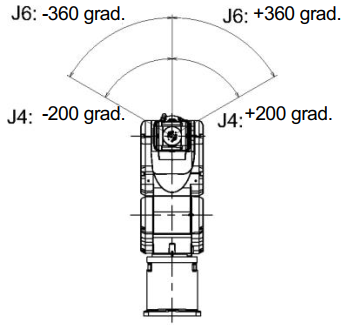

NOTA: La delimitación del espacio de trabajo se realizó con el punto P.

- **Tabla de parámetros DH.**

Para la delimitación de los parámetros DH primero se procedió a ubicar los marcos de referencia según el método de DH modificado:

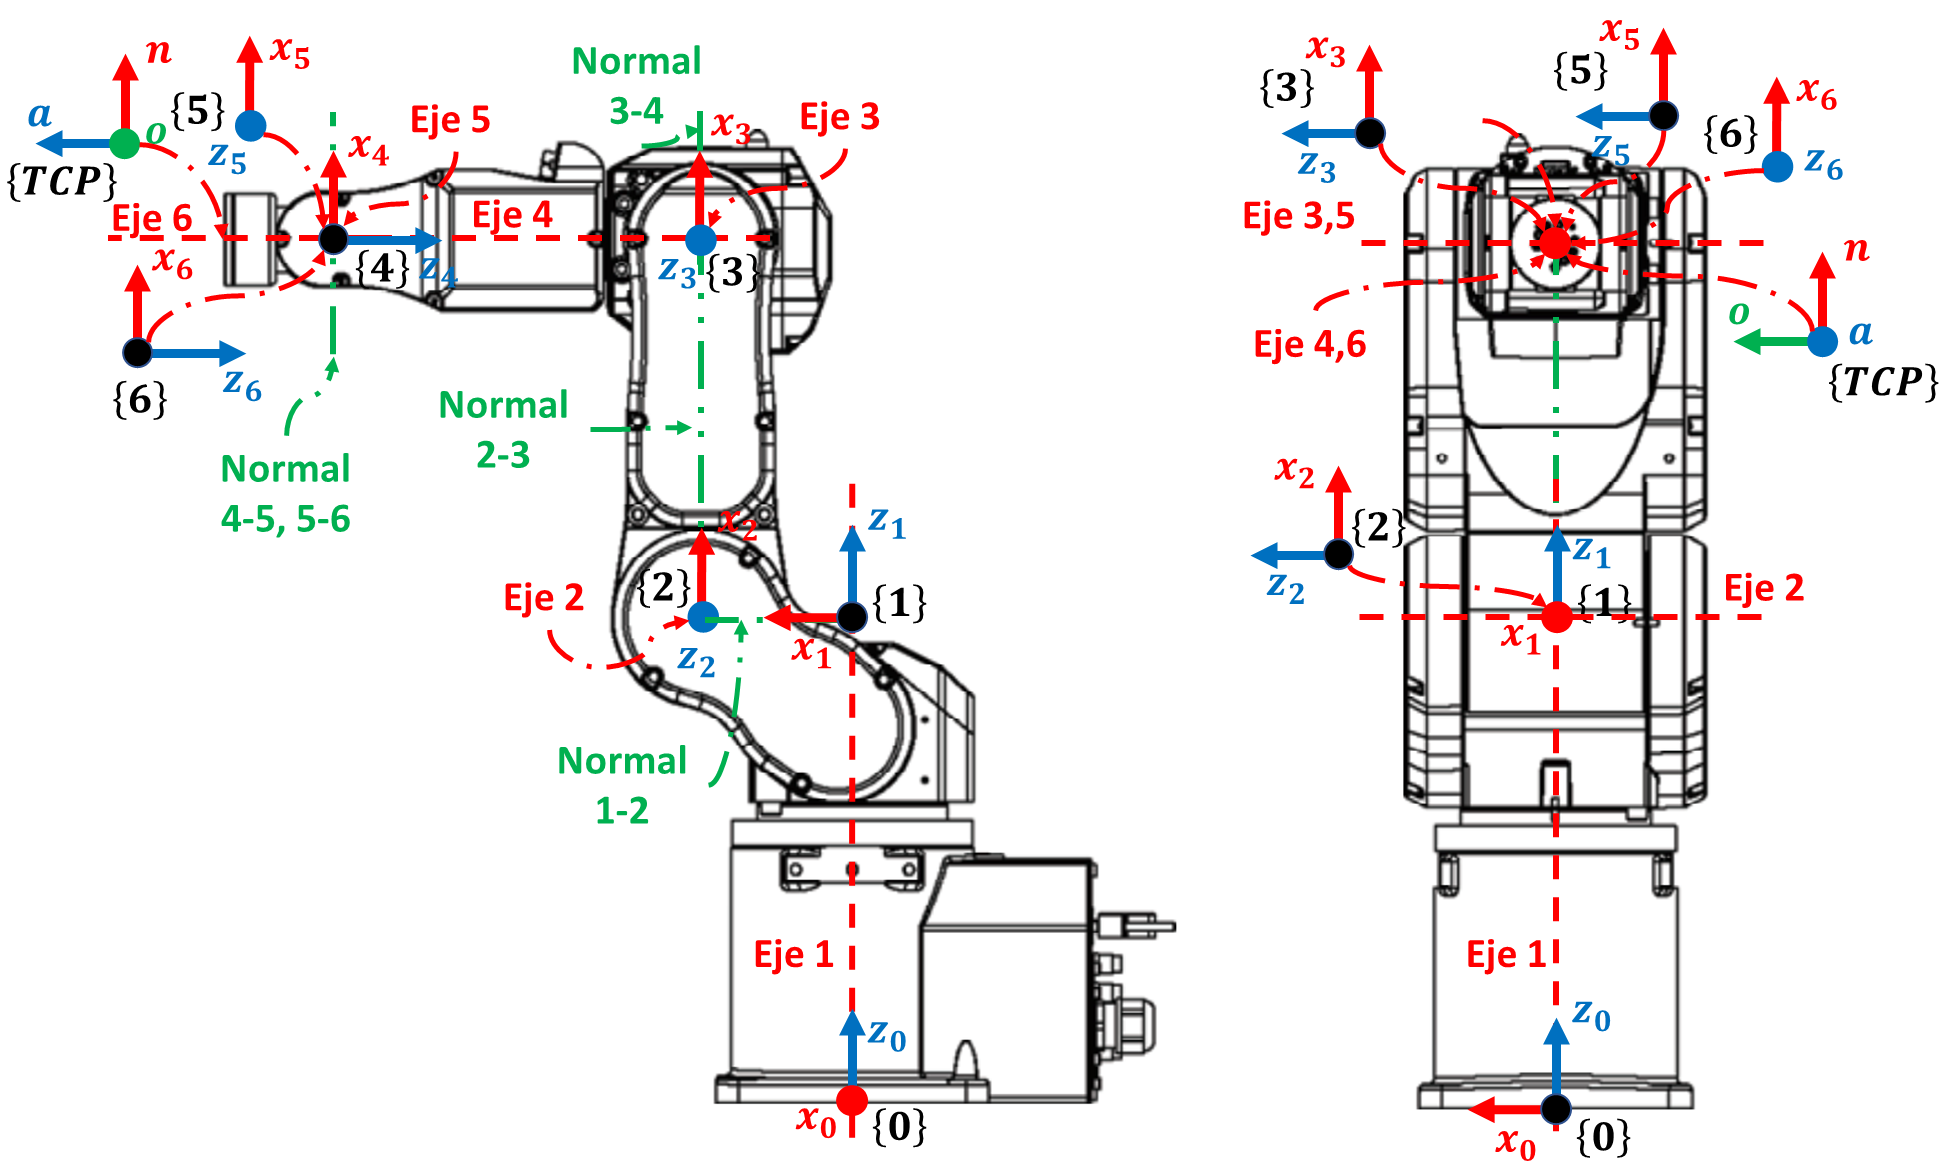

Teniendo en cuenta la anterior figura, se tuvo construyo la siguiente tabla:

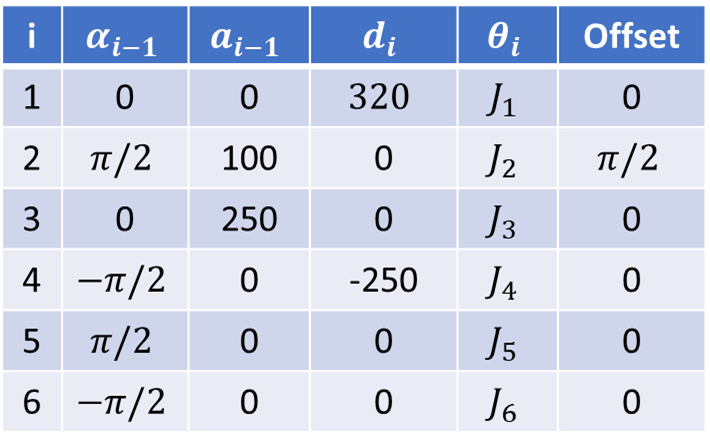

- **¿Qué software utiliza el fabricante para diseño de celdas o programación?**

Éste robot utiliza Epson RC+ que es un entorno de desarrollo de sistemas robóticos que incluye el lenguaje de programación SPEL+ y software para simulación en 3D; tiene opciones  integradas como la guía de visión, la alimentación de piezas, la guía de fuerza, el seguimiento de la banda transportadora entre otras.

- **¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad, etc.)**

Los estandares que maneja éste robot son: UL 1740 (sobre robots industriales y equipos robotizados), ANSI/RIA R15.06 (sobre robótica colaborativa, requisitos y pautas para el diseño seguro, las medidas de protección y la información para el uso de robots industriales, tambien se describe los peligros básicos asociados con los robots y proporciona requisitos para eliminar, o reducir adecuadamente, los riesgos asociados con éstos) y NFPA 79 (sobre la protección electrica y electronica contra sobrecorriente, sobretensiones, del cableado y los circuitos de seguridad).

Ademas, éste robot maneja un estandar de salas limpias ISO 14644-1 clase 3 la cual describe la clasificacion de limpieza del aire en ambientes controlados y salas blacas. Segun ésta norma la clasificacion del aire se realiza en terminos de concentracion de particulas suspendidad, de igual forma segun ésta norma se consideran particulas en un rango de 0.1 a 5 micrometros.

- **Haga un análisis del diagrama de la capacidad de carga.**

El valor nominal maximo de la carga en éste robot es de 1kg, cueando se supera éste valor se debe realizar una configuracion mediante software que modificara automaticamente las velocidades y aceleraciones del robot correspondientes a la carga, en este proceso se modifica el valor del parametro Weight. Para el caso se debe ingresar el peso calculado en forma de peso equivalente suponiendo que la carga ésta ubicada en el extremo del brazo Nº 6. Dicho peso equivalente se calcula de la forma descrita en la siguiente imagen:

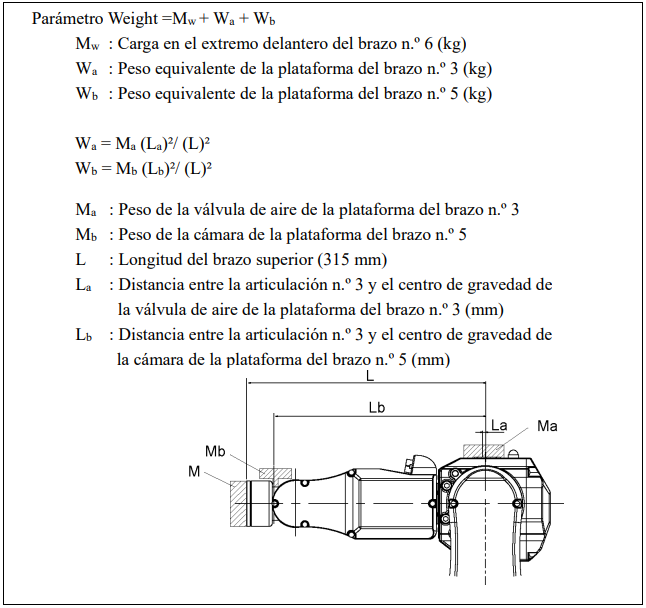

Porteriormente se realiza automaticamente un reajuste de la velocidad el mecanismo utilizando cómo base la velocidad con un peso nominal de 1kg siendo ésta el 100%. La variacion de la velocidad se ilustra en la siguiente imagen.

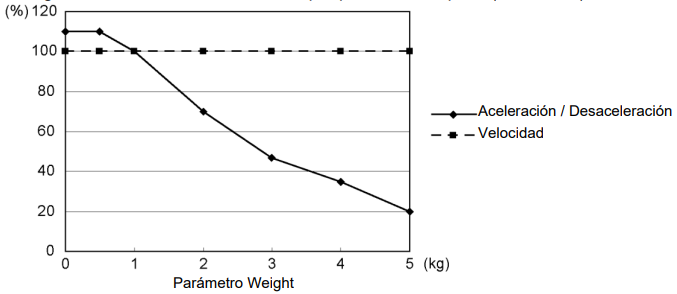

Por otro lado, cuando la carga util supera la carga util maxima se debe restringir la postura del brazo Nº 5 hacia abajo como se muestra en la siguiente imagen:

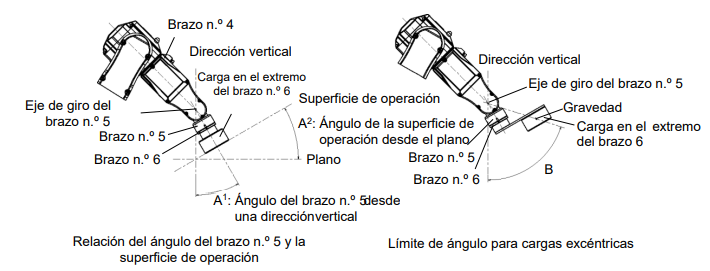

Se puede observar que la restriccion del angulo se realiza respecto a la linea perpendicular al plano de trabajo, diminuyendo su valor a medida que la carga aumenta debido a las limitaciones de torque del actuador. Cuando el manipulador opera verticalmente en relación con la superficie de operación, el límite del brazo Nº 5 es igual al límite del ángulo de operación ($A^2$).

El  siguiente gráfico muestra la relación del peso de la carga y el límite del ángulo ($A^1$) del brazo Nº 5. 

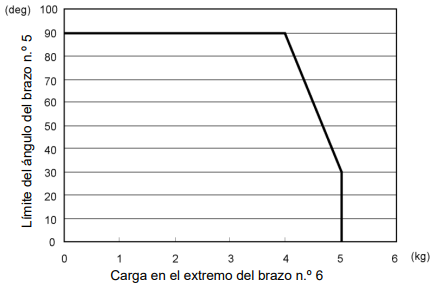

De ésto se puede extraer que el actuador que limita la capacidad de carga del robot es el encargado del movimiento de la articulacion entre el brazo Nº4 y el Nº5. De igual manera ésta articulacion queda completamentee inoperativa cuando el peso de la carga supera los 5kg.

**2. Según las características anteriores explique para qué aplicaciones se usa este robot.**

Teniendo en cuenta su diseño compacto (en posición de home, con dimensiones externas de 614.5mm x 640.5mm x 198mm), su tiempos de ciclo (más rapidos que robots SCARA de la competencia) y su capacidad de carga de 4kg, este robot posee una gran flexibilidad para realizar trabajos rápidos y espacios pequeños, los cuales caracterizan ambientes de trabajo como sectores de automatización de laboratorios, productos médicos y para el consumidor, de alimentos, automotor, de productos electrónicos, dispositivos periféricos para computadoras, semiconductores, plásticos, aparatos electrodomésticos y aeroespaciales.

## Iniciando

**Haciendo uso de MATLAB® y los toolboxes construya un modelo del robot o utilice uno disponible en los toolboxes y que corresponda al robot asignado.**

### Punto 1

**Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.**

clear all
T6b = trotx(pi)*transl([0 0 6.5]);

%     MDHm(thetai,      di,    ai-1,  alpha-1,   sigma, offset)
Links(1) = Link('revolute','alpha',0,    'a',0, 'd',32, 'offset',pi/2,'modified', 'qlim',[-17*pi/18 17*pi/18]);
Links(2) = Link('revolute','alpha',pi/2, 'a',10,'d',0,  'offset',pi/2,'modified', 'qlim',[-8*pi/9 13*pi/36]);
Links(3) = Link('revolute','alpha',0,    'a',25,'d',0,  'offset',0,   'modified', 'qlim',[-17*pi/60 5*pi/4]);
Links(4) = Link('revolute','alpha',-pi/2,'a',0, 'd',-25,'offset',0,   'modified', 'qlim',[-10*pi/9 10*pi/9]);
Links(5) = Link('revolute','alpha',pi/2, 'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-3*pi/4 3*pi/4]);
Links(6) = Link('revolute','alpha',-pi/2,'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-2*pi 2*pi]);

Epson_C4 = SerialLink(Links,'name','Epson C4','tool',T6b)

 
Epson_C4 = 
 
Epson C4 (6 axis, RRRRRR, modDH, fastRNE)                                     
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|         32|          0|          0|      1.571|             
|  2|         q2|          0|         10|      1.571|      1.571|             
|  3|         q3|          0|         25|          0|          0|             
|  4|         q4|        -25|          0|     -1.571|          0|             
|  5|         q5|          0|          0|      1.571|          0|             
|  6|         q6|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                    

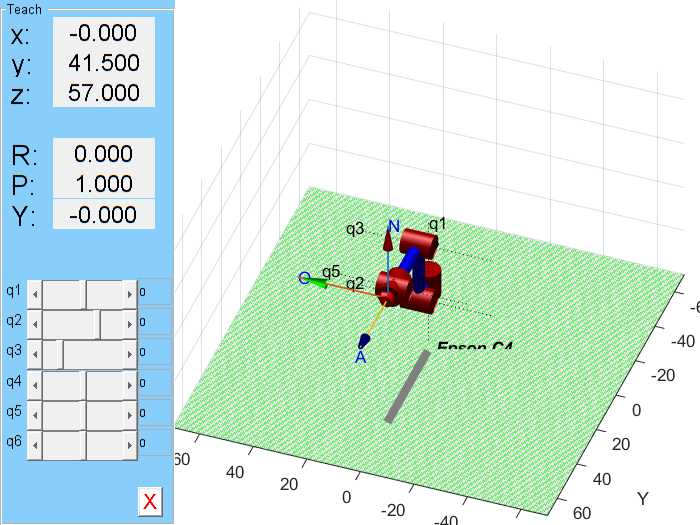

% PLOTEAR MTH ROBOT
close all
figure("Name","RVC")
hold on
%trplot(eye(4), 'width',0.75,'frame','0','arrow')
Epson_C4.plot([0 0 0 0 0 0],'workspace',[-70 70 -70 70 0 90],'noa','jaxes','view',[-160 40])
axis([-70 70 -70 70 0 90])
Epson_C4.teach()

### Punto 2

**Considerando el robot asignado, construya el modelo del robot utilizando RST.**

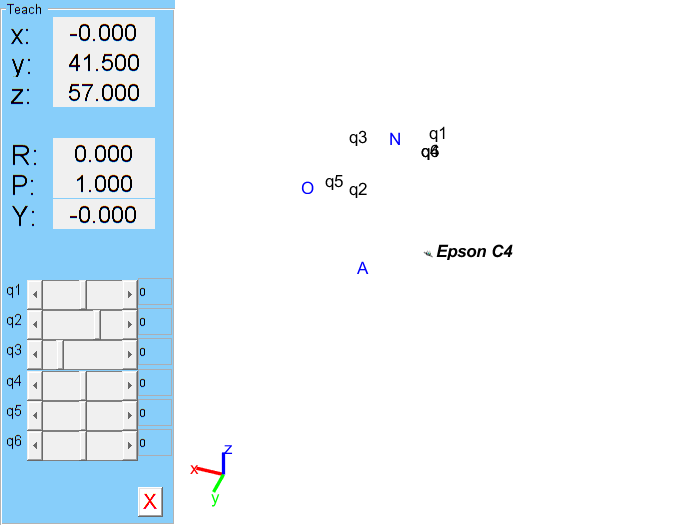

dhparams = [0,   0,	   0.32, 0;
            0.10,pi/2, 0     0;
            0.25,0,	   0,  	 0;
            0,   -pi/2,-0.25,0;
            0,   pi/2, 0,    0;
            0,   -pi/2,0 ,   0;
            0,   pi,   0.065,0];
robot = rigidBodyTree;

body1 = rigidBody('body1');
body2 = rigidBody('body2');
body3 = rigidBody('body3');
body4 = rigidBody('body4');
body5 = rigidBody('body5');
body6 = rigidBody('body6');
body7 = rigidBody('TCP');

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = pi/2;
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = pi/2;
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
jnt7 = rigidBodyJoint('jntTCP','revolute');
jnt7.HomePosition = 0;

setFixedTransform(jnt1,dhparams(1,:),'mdh');
setFixedTransform(jnt2,dhparams(2,:),'mdh');
setFixedTransform(jnt3,dhparams(3,:),'mdh');
setFixedTransform(jnt4,dhparams(4,:),'mdh');
setFixedTransform(jnt5,dhparams(5,:),'mdh');
setFixedTransform(jnt6,dhparams(6,:),'mdh');
setFixedTransform(jnt7,dhparams(7,:),'mdh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;
body7.Joint = jnt7;

addBody(robot,body1,'base')
addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')
addBody(robot,body7,'body6')
config_home = homeConfiguration(robot);
config = homeConfiguration(robot);
%config(2).JointPosition = pi/2;
%poseNow = getTransform(robot,config,'body7')

show(robot,config);
axis([-0.70 0.70 -0.70 0.70 0 0.90])

### Punto 3

**Compare los dos métodos.**

Para el modelado y simulaciones de la cinemática de un robot, entre *Toolbox de Peter Corke *(RVC) y *Robotics Systems Toolbox *(RST) se denotan varias semejanzas y diferencias:

- Para la declaración de eslabones (Link para RVC y RigidBody-RigidBodyJoint para RST) es más simple para el RVC para el caso que se desee hacer una cadena cinemática simple, ya que para este solo es necesario una función, en cambio para el RST se necesita una serie de funciones para lograrlo (crear body, crear junta, configurar offset de junta, configurar parámetros junta, enlazar body con junta).

- Sin embargo, la creación de múltiples cadenas cinemáticas conectadas entre sí, solo es posible para el RST, ya que la creación del robot, mientras que el RVC se hace solo con un comando (*SerialLink*), para el RST se debe enlazar manualmente los elabones entre sí, mediante *addBody* por lo que hay mas libertad en el orden de enlace entre ellas.

- Para el RVC hay una mayor compatibilidad con las variables simbólicas, lo que permite más libertad en el análisis de las matrices de transformación, entre otros.

- Para el RVC hay una mejor interfaz y funcionalidades al momento de la visualización y experimentación con robot, ya que presenta una simulación mas amigable a la vista e interacciones con el usuario.

- Para el RST hay una mejor interconexión con programas externos como ROS y GAZEBO que permite usar muchas de las funcionalidades de estos programas que enriquecen el proceso de aprendizaje.

## Modelo Geométrico Directo

### Punto 1

**Halle el modelo geométrico directo de su robot asignado usando DH modificado.**

syms J1 J2 J3 J4 J5 J6
T01 = vpa(Links(1).A(J1),3)

$$T01 = \left(\begin{array}{cccc} \cos\left(J_{1}+1.57\right) & -1.0\,\sin\left(J_{1}+1.57\right) & 0 & 0\\ \sin\left(J_{1}+1.57\right) & \cos\left(J_{1}+1.57\right) & 0 & 0\\ 0 & 0 & 1.0 & 32.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T12 = vpa(Links(2).A(J2),3)

$$T12 = \left(\begin{array}{cccc} \cos\left(J_{2}+1.57\right) & -1.0\,\sin\left(J_{2}+1.57\right) & 0 & 10.0\\ 6.12e-17\,\sin\left(J_{2}+1.57\right) & 6.12e-17\,\cos\left(J_{2}+1.57\right) & -1.0 & 0\\ \sin\left(J_{2}+1.57\right) & \cos\left(J_{2}+1.57\right) & 6.12e-17 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T23 = vpa(Links(3).A(J3),3)

$$T23 = \left(\begin{array}{cccc} \cos\left(J_{3}\right) & -1.0\,\sin\left(J_{3}\right) & 0 & 25.0\\ \sin\left(J_{3}\right) & \cos\left(J_{3}\right) & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T34 = vpa(Links(4).A(J4),3)

$$T34 = \left(\begin{array}{cccc} \cos\left(J_{4}\right) & -1.0\,\sin\left(J_{4}\right) & 0 & 0\\ 6.12e-17\,\sin\left(J_{4}\right) & 6.12e-17\,\cos\left(J_{4}\right) & 1.0 & -25.0\\ -1.0\,\sin\left(J_{4}\right) & -1.0\,\cos\left(J_{4}\right) & 6.12e-17 & -1.53e-15\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T45 = vpa(Links(5).A(J5),3)

$$T45 = \left(\begin{array}{cccc} \cos\left(J_{5}\right) & -1.0\,\sin\left(J_{5}\right) & 0 & 0\\ 6.12e-17\,\sin\left(J_{5}\right) & 6.12e-17\,\cos\left(J_{5}\right) & -1.0 & 0\\ \sin\left(J_{5}\right) & \cos\left(J_{5}\right) & 6.12e-17 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T56 = vpa(Links(6).A(J6),3)

$$T56 = \left(\begin{array}{cccc} \cos\left(J_{6}\right) & -1.0\,\sin\left(J_{6}\right) & 0 & 0\\ 6.12e-17\,\sin\left(J_{6}\right) & 6.12e-17\,\cos\left(J_{6}\right) & 1.0 & 0\\ -1.0\,\sin\left(J_{6}\right) & -1.0\,\cos\left(J_{6}\right) & 6.12e-17 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

T6b

T6b =     1.0000         0         0         0
         0   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000   -6.5000
         0         0         0    1.0000


T0b = vpa(T01*T12*T23*T34*T45*T56*T6b,3)

### Punto 2

**Haciendo uso del modelo directo haga una representación del espacio de trabajo alcanzable del robot.**

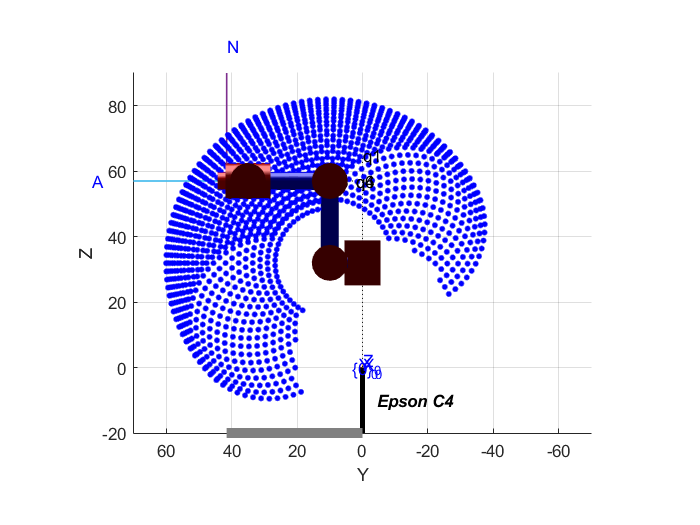

dtheta = 0.1;
Lim_J1 = -17*pi/18:dtheta:17*pi/18;
Lim_J2 = -8*pi/9:dtheta:13*pi/36;
Lim_J3 = -17*pi/60:dtheta:5*pi/4;
Lim_J4 = -10*pi/9:dtheta:10*pi/9;
Lim_J5 = -3*pi/4:dtheta:3*pi/4;
Lim_J6 = -2*pi:dtheta:2*pi;

n1 = length(Lim_J2)*length(Lim_J3)*length(Lim_J5);
workspace1 = zeros(n1,3);

m1 = 1;
for q1 = 0
    for q2 = Lim_J2
        for q3 = Lim_J3
            for q4 = 0
                for q5 = Lim_J5
                    for q6 = 0                            
                        if ~((q2>-160*pi/180 && q2<-157*pi/180) && (q3>135*pi/180 && q3<225*pi/180)) && ~(q3>-10*q2/13 + 225*pi/180) && ~(q3<-53*q2/40 -157*pi/180) && ~(q2<-135*pi/180)
                            config(1).JointPosition = q1 + pi/2;
                            config(2).JointPosition = q2 + pi/2;
                            config(3).JointPosition = q3;
                            config(4).JointPosition = q4;
                            config(5).JointPosition = q5;
                            config(6).JointPosition = q6;
                            poseNow = getTransform(robot,config,'body6');
                            
                            workspace1(m1,:) = [poseNow(1,4),poseNow(2,4),poseNow(3,4)];
                            
                            m1 = m1 + 1;
                        end
                    end
                end
            end
        end
    end
end

workspace1 = workspace1(1:m1-1,:);

% PLOTEAR ESPACIO DE TRABAJO 1 DE ROBOT EPSON C4
close all
figure("Name","Punto 2_2_1")
hold on
trplot(eye(4), 'width',0.75,'frame','0','arrow')
Epson_C4.plot([0 0 0 0 0 0],'workspace',[-70 70 -70 70 -20 90],'noa','jaxes','view',[-90 0])
axis([-70 70 -70 70 0 90])
for i = 1:m1-1
   plot3(workspace1(i,1)*100,workspace1(i,2)*100,workspace1(i,3)*100,'b.','MarkerSize',10);
end
axis([-70 70 -70 70 -20 90])

### Punto 3

**Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.**

En el manual técnico del robot se recomienda el siguiente diagrama de flujo para el proceso de calibración:

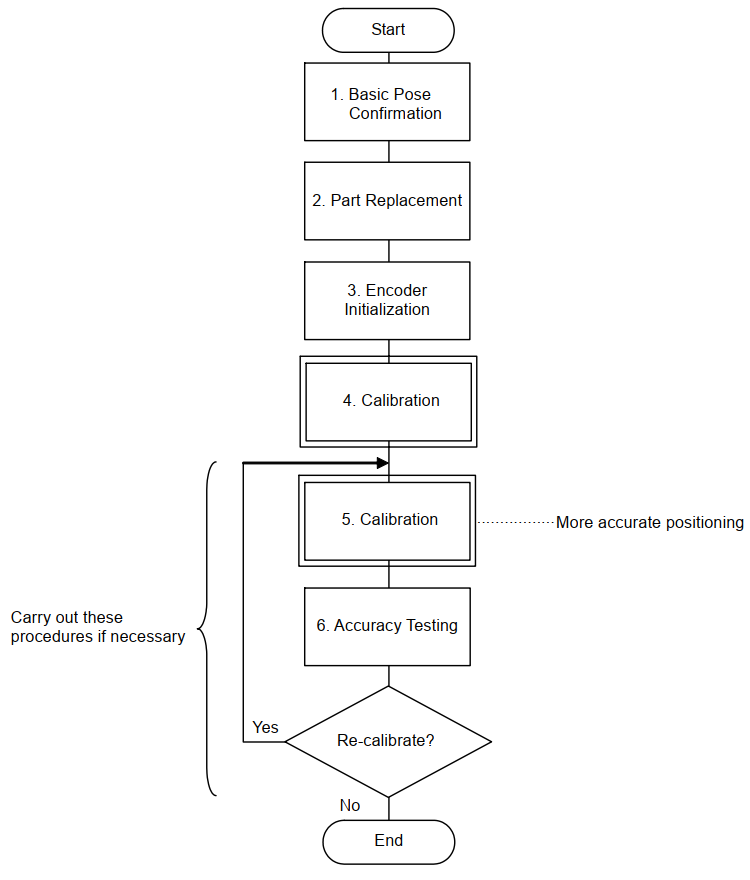

Donde el primer paso de "Confirmación de postura básica" dice textualmente: "Se necesitan los datos de pose (datos de punto) antes del reemplazo de la pieza (motores, unidad de engranaje reductor o correa) para la calibración. Verifique los valores de pulso registrados de la pose básica obtenidos en *Configuración y operación 3.7 Revisión de la orientación básica"*. En la sección 3.7 se indica que la orientación básica para el proceso de calibración es:

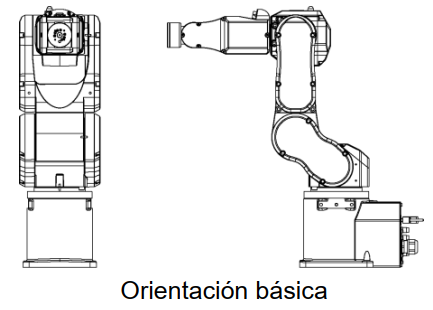

Los cuales en secciones anteriores dieron sus respectivas cotas:

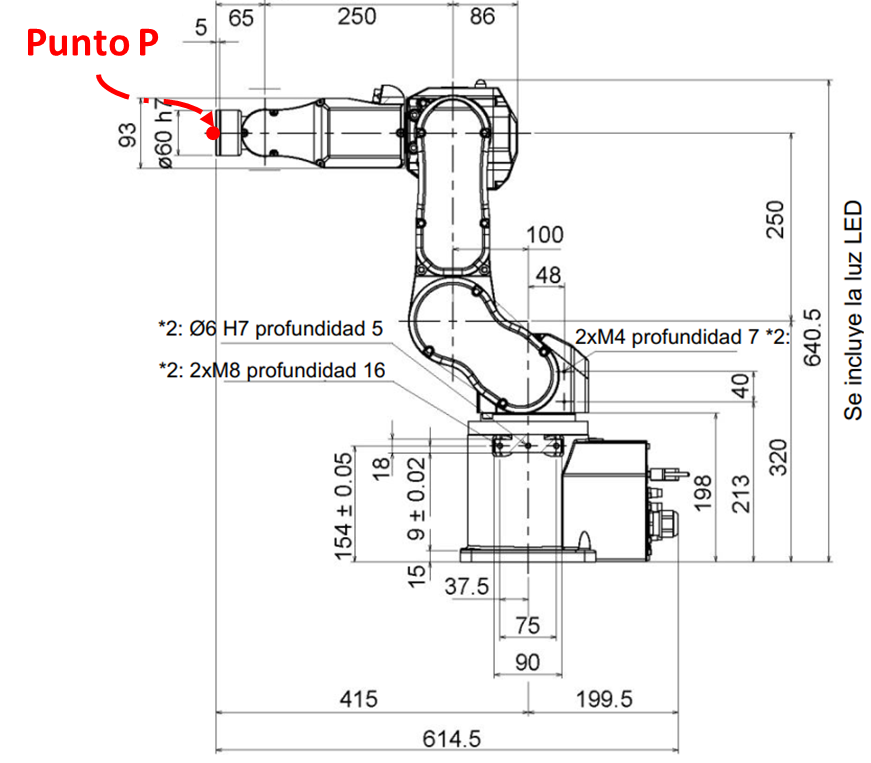

Es decir que el punto de calibración P (que en casi todas las gráficas del manual corresponde con la intersección entre los ejes de las articulaciones 4 y 5) es:

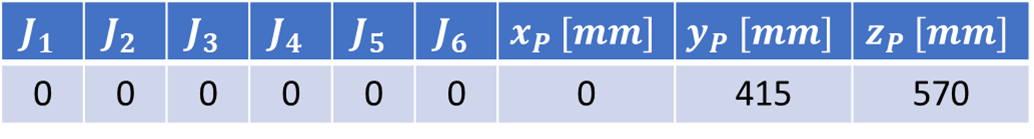

T01_ = double(subs(T01,'J1',0));
T12_ = double(subs(T12,'J2',0));
T23_ = double(subs(T23,'J3',0));
T34_ = double(subs(T34,'J4',0));
T45_ = double(subs(T45,'J5',0));
T56_ = double(subs(T56,'J6',0));
poseHome = T01_*T12_*T23_*T34_*T45_*T56_*T6b;
P = [poseHome(1,4)*10,poseHome(2,4)*10,poseHome(3,4)*10] % cm -> mm

P =     0.0000  415.0000  570.0000


### Punto 4

**Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores. **

% RVC
poseHome1 = Epson_C4.fkine([0 0 0 0 0 0]);
P1 = [poseHome1(1,4)*10,poseHome1(2,4)*10,poseHome1(3,4)*10] % cm -> mm

P1 =    -0.0000  415.0000  570.0000


% RST
poseHome2 = getTransform(robot,config_home,'TCP');
P2 = [poseHome2(1,4)*1000,poseHome2(2,4)*1000,poseHome2(3,4)*1000] % m -> mm

P2 =    -0.0000  415.0000  570.0000


### Punto 5

**Compare los métodos.**

Ambos métodos dispuestos por RVC y RST son rápidos de usar porque solo necesita una función. Sin embargo, mientras que la entrada del primero es directamente un vector con los valores de los ángulos de las articulaciones, el segundo necesita especificarse estos valores mediante el uso de estructuras, lo cual requiere de entre 1 hasta n+1 (con n el número de articulaciones) funciones adicionales (para valores diferentes a Home, además que para esto siempre se debe tener en cuenta que los offset no se guardan. Aunque la ventaja que tiene este segundo toolbox, es que cuando se puede especificar que matriz de transformación se quiere obtener, seleccionando el body deseado

### Punto 6

**Exprese la pose del efector en matriz de cosenos directores.**

Cos_dir_mat = t2r(poseHome)

Cos_dir_mat =    -0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000


### Punto 7

**Exprese la pose del efector final en coordenadas generalizadas del efector final.**

Coor_Gen_TCP = [poseHome(1:3,4);tr2rpy(poseHome)']

Coor_Gen_TCP =     0.0000
   41.5000
   57.0000
   -1.5708
    0.0000
   -1.5708


### Punto 8

**Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo *****Slider*****, visualizar el robot y la posición del efector final.**

Para la GUI se debe abrir el archivo contiguo a la entrga llamad untited y ejecutar el comando untitled en la ventana de comandos de matlab una vez alli podra realizar el cambio de los parametros dentro de la GUI, para ello lo primero que debe hacer es inicialiarla poniendo en las casillas vacias el valor 0 , despues de eso se debe pulsar el boton forward y asi podra asignando valores entre -90 y 90  mover libremente el robot dentro de la GUI, esta es la unica forma de usar la GUI los sliders estan desconectados del modelo. 

### Punto 9

**En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.  **